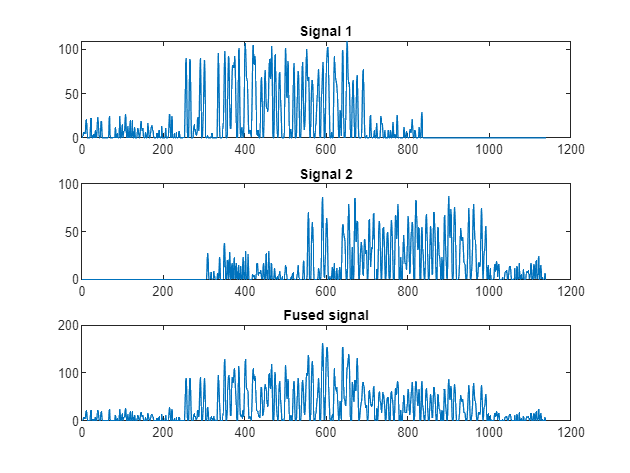

clear
load("ConvolutionArray.mat")


%Signals shorter for readability reasons
data_binary1 = [1 0 0 0 1 1 0 1 0 1 0 0]'; 
data_binary2 = [0 1 1 0 1 1 1 1 1 0 0 0]';
amplitude1 = 0.4;
amplitude2 = 0.3;
delay = 300;

packet_bits1 = GenerateBits(data_binary1);
packet_bits2 = GenerateBits(data_binary2);

[idealSignal, ~, ~, ADCsignal1, ~] = GenerateSignal(packet_bits1, amplitude1);
[idealSignal2, ~, ~, ADCsignal2, ~] = GenerateSignal(packet_bits2, amplitude2);
ADCsignal1 = [ADCsignal1, zeros(1, delay)];
ADCsignal2 = [zeros(1, delay), ADCsignal2];
fused_signal = ADCsignal1 + ADCsignal2;

figure
subplot(3, 1, 1)
plot(ADCsignal1)
title("Signal 1")
subplot(3, 1, 2)
plot(ADCsignal2)
title("Signal 2")
subplot(3, 1, 3)
plot(fused_signal)
title("Fused signal")

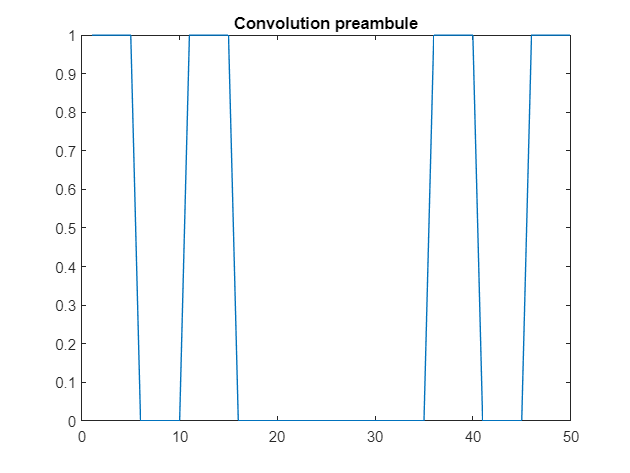

convIndex = 1; %Basic convolution

correlation1 = GenerateConv(ADCsignal1, convTypes(convIndex).convPreambule);
correlation2 = GenerateConv(ADCsignal2, convTypes(convIndex).convPreambule);
correlation_fused = GenerateConv(fused_signal, convTypes(convIndex).convPreambule);

target_point_1 = convTypes(convIndex).expectedMaximum;
target_point_2 = convTypes(convIndex).expectedMaximum + delay;

target_points_x = [target_point_1, target_point_2];
target_points_y = [correlation_fused(target_point_1), correlation_fused(target_point_2)];

figure
plot(convTypes(convIndex).convPreambule)
title("Convolution preambule")

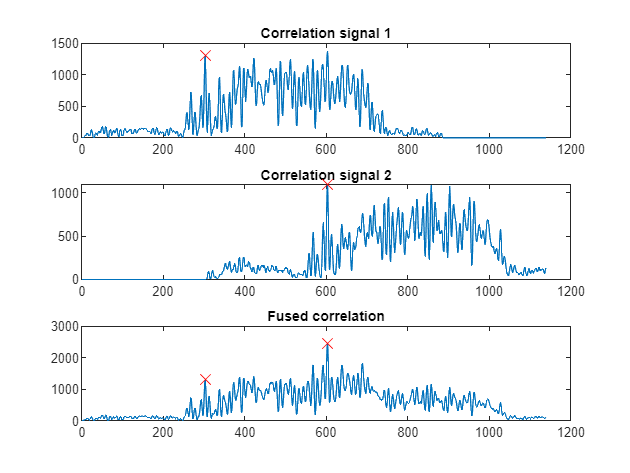


figure
subplot(3, 1, 1)
plot(correlation1)
hold on
scatter(target_point_1, correlation1(target_point_1),100, 'x','red', 'DisplayName', "Target hit")
title("Correlation signal 1")
hold off
subplot(3, 1, 2)
plot(correlation2)
hold on
scatter(target_point_2, correlation2(target_point_2),100, 'x','red', 'DisplayName', "Target hit")
title("Correlation signal 2")
hold off
subplot(3, 1, 3)
plot(correlation_fused)
hold on
scatter(target_points_x, target_points_y,100, 'x','red', 'DisplayName', "Target hit")
title("Fused correlation")
hold off

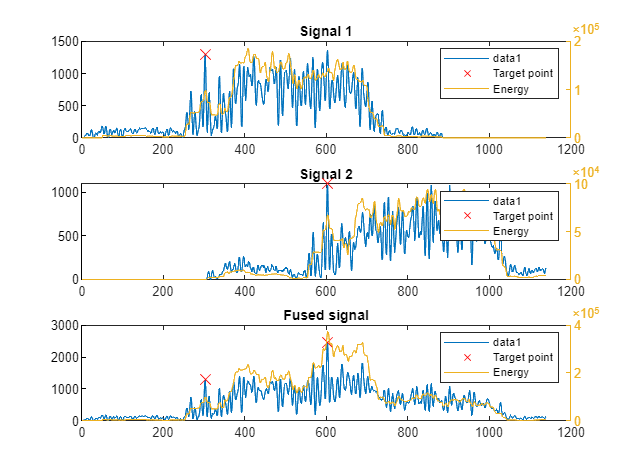

energy1 = GenerateEnergy(ADCsignal1, length(convTypes(convIndex).convPreambule));
energy2 = GenerateEnergy(ADCsignal2, length(convTypes(convIndex).convPreambule));
energy_fused = GenerateEnergy(fused_signal, length(convTypes(convIndex).convPreambule));

figure
subplot(3, 1, 1)
plot(correlation1)
hold on
scatter(target_point_1, correlation1(target_point_1),100, 'x','red', 'DisplayName', "Target point")
yyaxis right
plot(energy1, 'DisplayName', "Energy")
legend()
title("Signal 1")
hold off
subplot(3, 1, 2)
plot(correlation2)
hold on
scatter(target_point_2, correlation2(target_point_2),100, 'x','red', 'DisplayName', "Target point")
yyaxis right
plot(energy2, 'DisplayName', "Energy")
legend()
title("Signal 2")
hold off
subplot(3, 1, 3)
plot(correlation_fused)
hold on
scatter(target_points_x, target_points_y,100, 'x','red', 'DisplayName', "Target point")
yyaxis right
plot(energy_fused, 'DisplayName', "Energy")
legend()
title("Fused signal")
hold off

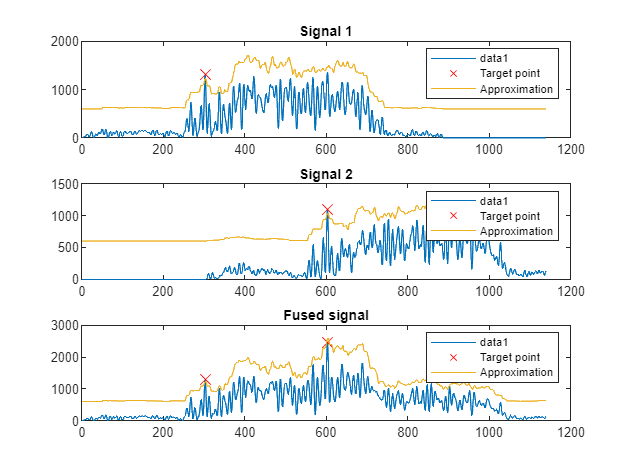

load("tempNeigiamasRodiklisData.mat", "allApproximations") %For approximation data

approx_index = 1; %Normal mean

approximation1 = GenerateApprox(energy1, allApproximations(approx_index));
approximation2 = GenerateApprox(energy2, allApproximations(approx_index));
approximation_fused = GenerateApprox(energy_fused, allApproximations(approx_index));

figure
subplot(3, 1, 1)
plot(correlation1)
hold on
scatter(target_point_1, correlation1(target_point_1),100, 'x','red', 'DisplayName', "Target point")
plot(approximation1, 'DisplayName', "Approximation")
legend()
title("Signal 1")
hold off
subplot(3, 1, 2)
plot(correlation2)
hold on
scatter(target_point_2, correlation2(target_point_2),100, 'x','red', 'DisplayName', "Target point")
plot(approximation2, 'DisplayName', "Approximation")
legend()
title("Signal 2")
hold off
subplot(3, 1, 3)
plot(correlation_fused)
hold on
scatter(target_points_x, target_points_y,100, 'x','red', 'DisplayName', "Target point")
plot(approximation_fused, 'DisplayName', "Approximation")
legend()
title("Fused signal")
hold off